Simulated Swarm stuff

load('pathdata.mat');

%[leader_pos_store, leader_vel_store, agent_pos_store, agent_vel_store] = interactive_simulation()

num_agents = 2;
p = zeros(num_agents, 2);
v = zeros(num_agents, 2);
p_leader_current = [-4, 0];
v_leader_current = [-4, 0];

x_pos = leader_pos_store(:,1)'

x_pos =    -3.9974   -3.9948   -3.9922   -3.9897   -3.9871   -3.9845   -3.9819   -3.9793   -3.9767   -3.9741   -3.9715   -3.9690   -3.9664   -3.9638   -3.9612   -3.9506   -3.8967   -3.8367   -3.7767   -3.7167   -3.6567   -3.5967   -3.5367   -3.4767   -3.4167   -3.3567   -3.2967   -3.2367   -3.1767   -3.1167   -3.0567   -2.9967   -2.9367   -2.8767   -2.8167   -2.7567   -2.6967   -2.6367   -2.5767   -2.5167   -2.4567   -2.3967   -2.3367   -2.2767   -2.2167   -2.1567   -2.0967   -2.0367   -1.9767   -1.9167


y_pos = leader_pos_store(:,2)'

y_pos =    -0.0007   -0.0014   -0.0021   -0.0028   -0.0035   -0.0042   -0.0049   -0.0057   -0.0064   -0.0071   -0.0078   -0.0085   -0.0092   -0.0099   -0.0106   -0.0113   -0.0120   -0.0127   -0.0134   -0.0141   -0.0148   -0.0155   -0.0163   -0.0170   -0.0177   -0.0184   -0.0191   -0.0198   -0.0205   -0.0212   -0.0219   -0.0226   -0.0233   -0.0240   -0.0247   -0.0254   -0.0262   -0.0269   -0.0276   -0.0283   -0.0290   -0.0297   -0.0304   -0.0311   -0.0318   -0.0325   -0.0332   -0.0339   -0.0346   -0.0353



x_vel = leader_vel_store(:,1)'

x_vel =     0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0106    0.0539    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600


y_vel = leader_vel_store(:,1)'

y_vel =     0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0106    0.0539    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600



num_steps = 130;

for i = 1:num_agents
    eval(sprintf('p_%d = [0; 0];', i));
    eval(sprintf('v_%d = [0; 0];', i));
end

p_1 = [-5; -1];
p_2 = [-5; 1];
%p_3 = [0; -2];
p = [p_1'; p_2'];

collision_count = 0;

for i = 1:num_steps
    N = neighbor_calc(p, num_agents);
    v = agent_velocity(N, p, v, p_leader_current, v_leader_current, num_agents);
    p = position_update(p, v);
    
    for j = 1:num_agents
            eval(sprintf('p_%d(:, end+1) = p(%d, :)'';', j, j)); 
            eval(sprintf('v_%d(:, end+1) = v(%d, :)'';', j, j));
    end

    p_leader_current = [x_pos(i), y_pos(i)];
    v_leader_current = [x_vel(i), y_vel(i)];

    collision_radius = 0.05;
    collisions = check_collisions(p, collision_radius);
    if any(collisions(:))
        collision_count = collision_count + 1;
    end
end

disp(['Total Collision Count: ', num2str(collision_count)]);

Total Collision Count: 0


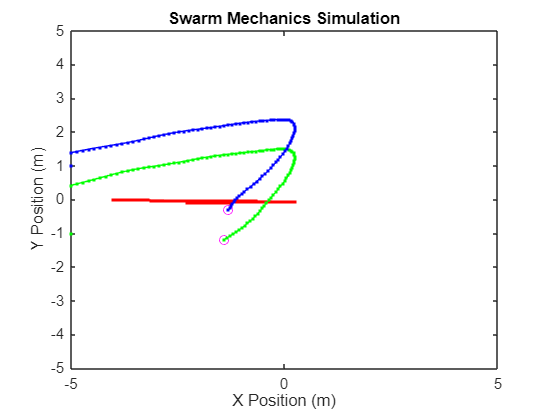


figure;
plot(x_pos, y_pos, 'r.-'); 
hold on;
for i = 1:num_agents
    plot(p(i, 1), p(i, 2), 'mo'); 
    plot(p_1(1, :), p_1(2, :), 'g.-');
    plot(p_2(1, :), p_2(2, :), 'b.-');
    %plot(p_3(1, :), p_3(2, :), 'c.-')
end
xlabel('X Position (m)');
ylabel('Y Position (m)');
axis([-5, 5, -5, 5]);
title('Swarm Mechanics Simulation');

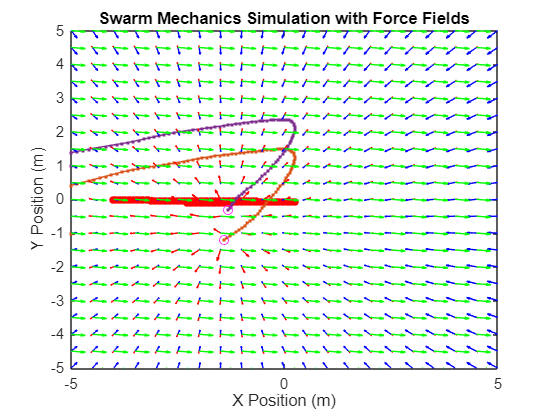

% Parameters for the forces
k_c = 0.05;     % cohesion
k_a = 0.1;      % alignment
k_s = 0.8;      % separation
r_0 = 0.9;      % avoidance range
k_avoid = 0.8;  % repulsion strength

% Grid of hypothetical positions for agent 1
[x_grid, y_grid] = meshgrid(-5:0.5:5, -5:0.5:5);
u_sep = zeros(size(x_grid));  % Separation force (x-component)
v_sep = zeros(size(y_grid));  % Separation force (y-component)

u_coh = zeros(size(x_grid));  % Cohesion force (x-component)
v_coh = zeros(size(y_grid));  % Cohesion force (y-component)

u_align = zeros(size(x_grid));  % Alignment force (x-component)
v_align = zeros(size(y_grid));  % Alignment force (y-component)

% Agent 1's current position and velocity
p1 = p(1, :);  % Position of agent 1
v1 = v(1, :);  % Velocity of agent 1

% Compute forces at each grid point
% Compute forces at each grid point
for ix = 1:size(x_grid, 1)
    for iy = 1:size(y_grid, 2)
        hypothetical_pos = [x_grid(ix, iy), y_grid(ix, iy)];

        % Initialize force components for each grid point
        F_sep = zeros(1, 2);
        F_coh = zeros(1, 2);
        F_align = zeros(1, 2);
        
        % Iterate through all agents to calculate separation, cohesion, and alignment
        for i = 1:num_agents
            % Separation Force (Avoidance)
            r_vec = hypothetical_pos - p(i, :);  % Vector from agent i to hypothetical position
            r = norm(r_vec);  % Distance
            F_sep = F_sep + k_s * (r_vec / r) * log(1 + r_0 / r);
                
            % Cohesion Force (Attraction to neighbors)
            F_coh = F_coh + k_c * (p(i, :) - hypothetical_pos);
                
            % Alignment Force (Align with neighbors)
            F_align = F_align + k_a * (v(i, :) - v1);
        end
        
        % Store the computed forces
        u_sep(ix, iy) = F_sep(1);
        v_sep(ix, iy) = F_sep(2);

        u_coh(ix, iy) = F_coh(1);
        v_coh(ix, iy) = F_coh(2);

        u_align(ix, iy) = F_align(1);
        v_align(ix, iy) = F_align(2);
    end
end

% Main Plot for the Swarm Simulation
figure;

% Plot the positions of the agents
plot(x_pos, y_pos, 'r.-', "MarkerSize", 15); 
hold on;

% Plot the positions and trajectories of the agents
for i = 1:num_agents
    % Ensure each agent's position is plotted, including agent 2 (p_2)
    eval(sprintf('plot(p_%d(1,:), p_%d(2,:), ''.-'');', i, i));  % Plot the trajectory
    plot(p(i, 1), p(i, 2), 'mo'); % Plot the current position
end

% Overlay the force fields as quiver plots
quiver(x_grid, y_grid, u_sep, v_sep, 'r', 'AutoScaleFactor', 0.5);   % Separation
quiver(x_grid, y_grid, u_coh, v_coh, 'b', 'AutoScaleFactor', 0.5);   % Cohesion
quiver(x_grid, y_grid, u_align, v_align, 'g', 'AutoScaleFactor', 0.5); % Alignment

% Labeling and formatting
xlabel('X Position (m)');
ylabel('Y Position (m)');
axis([-5, 5, -5, 5]);
title('Swarm Mechanics Simulation with Force Fields');

hold off;